%a)
clear
fprintf("\n----\nSobreamortiguada (E > 1)\n----\n")


----
Sobreamortiguada (E > 1)
----



E=2;                %coeficiente de amortiguamiento
wn=1;               %frecuencia natural no amortiguada
wd=wn*sqrt(1-E^2)   %frecuencia de amortiguamiento

wd = 0.0000 + 1.7321i

sigma=E*wn

sigma = 2


%
tr_sobreamortiguada=(pi - atan(wd/sigma)) / wd          %t de subida

tr_sobreamortiguada = -0.7603 - 1.8138i

tp_sobreamortiguada=pi/wd                               %t de pico

tp_sobreamortiguada = 0.0000 - 1.8138i

ts_sobreamortiguada=pi/sigma                            %t de establecimiento

ts_sobreamortiguada = 1.5708

Mp_sobreamortiguada = exp(-(sigma/wd)*pi)*100           %sobreoscilacion maxima

Mp_sobreamortiguada = -88.4205 - 46.7098i

Mp_sobreamortiguada = exp((-pi*E)/sqrt(1-E^2)) * 100

Mp_sobreamortiguada = -88.4205 - 46.7098i

%

n=[wn^wn];
d=[1 2*E*wn wn^2];

fdt=tf(n,d)


fdt =
 
        1
  -------------
  s^2 + 4 s + 1
 
Continuous-time transfer function.



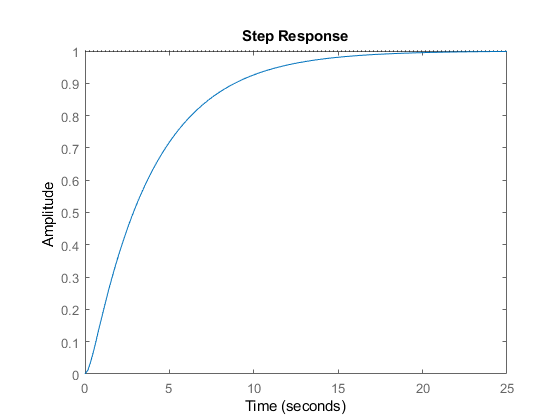

step(fdt) 


%nunca se llega a establecer la respuesta

%b)
clear 
fprintf("\n----\nCriticamente amortiguada (E = 1)\n----\n")


----
Criticamente amortiguada (E = 1)
----



E=1                 %coeficiente de amortiguamiento

E = 1

wn=1                %frecuencia natural no amortiguada

wn = 1

wd=wn*sqrt(1-E^2)   %frecuencia de amortiguamiento

wd = 0

sigma=E*wn

sigma = 1


%
tr_criticamente_amortiguada=(pi - atan(wd/sigma)) / wd      %t de subida

tr_criticamente_amortiguada = Inf

tp_criticamente_amortiguada=pi/wd                           %t de pico

tp_criticamente_amortiguada = Inf

ts_criticamente_amortiguada=pi/sigma                        %t de establecimiento

ts_criticamente_amortiguada = 3.1416

Mp_criticamente_amortiguada = exp(-(sigma/wd)*pi)*100       %sobreoscilacion maxima

Mp_criticamente_amortiguada = 0

Mp_criticamente_amortiguada = exp((-pi*E)/sqrt(1-E^2)) * 100

Mp_criticamente_amortiguada = 0

%

n=[wn^wn];
d=[1 2*E*wn wn^2];

fdt=tf(n,d)


fdt =
 
        1
  -------------
  s^2 + 2 s + 1
 
Continuous-time transfer function.



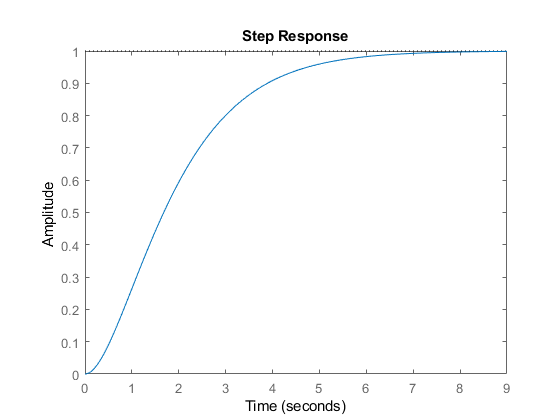

step(fdt) 


%nunca se llega a establecer la respuesta